m=3 %масса в кг

m = 3

fm=4%максимальная тяга в кг

fm = 4

y0=0% начальная высота в метрах

y0 = 0

yt=5%целевая высота в метрах

yt = 5

step=0.003%шаг итегрирования в секундах

step = 0.0030

Kp= 27%пропорциональный коэфицент 27

Kp = 27

Ki=-12.5 %итегральный коэфицент -12,5

Ki = -12.5000

Kd= 10%дифференциальный коэфицент 

Kd = 10

K=50 %общий коэфицент 

K = 50

Kp= K*Kp

Kp = 1350

Ki=K*Ki

Ki = -625

Kd= K*Kd

Kd = 500

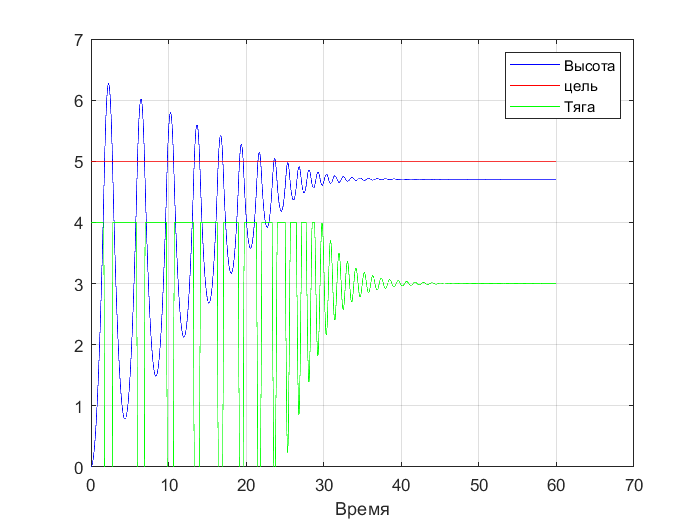


%сервисные переменные
g=9.81;%ускорение свободного падения
fm=fm*g;
a=0;% ускорение
f=0;%тяга
v=0;%скорость
n=0;%номер такта
t=0;%время
y=y0;%высота

I=0;
erl=0;%предыдущая ошибка
DATAH=[];
DATAT=[];
DATAA=[];
DATAV=[];
DATAF=[];


while  n<20000
    n=n+1;
    t=t+step;
    f=Kp*(yt-y)+I+Ki*(yt-y)+Kd*((yt-y)-erl)/step;
    if f>=fm 
        f=fm;
    end
    if f<=0
        f=0;
    end
    I=Ki*(yt-y);
    a=(f/m)-g;
    v=v+a*step;
    y=y+v*step;
    if y<=0
        y=0;
    end
    erl=yt-y;
    
    DATAH(n)=y;
    DATAT(n)=t;
    DATAA(n)=a;
    DATAV(n)=v;
    DATAF(n)=f/g;
    
end

%subplot(4,1,1)
Y=yt+DATAT*0;
plot(DATAT,DATAH,'b',DATAT,Y,'r',DATAT,DATAF,'g')
legend("Высота","цель","Тяга")
grid on;
%ylabel("Высота")
xlabel("Время")

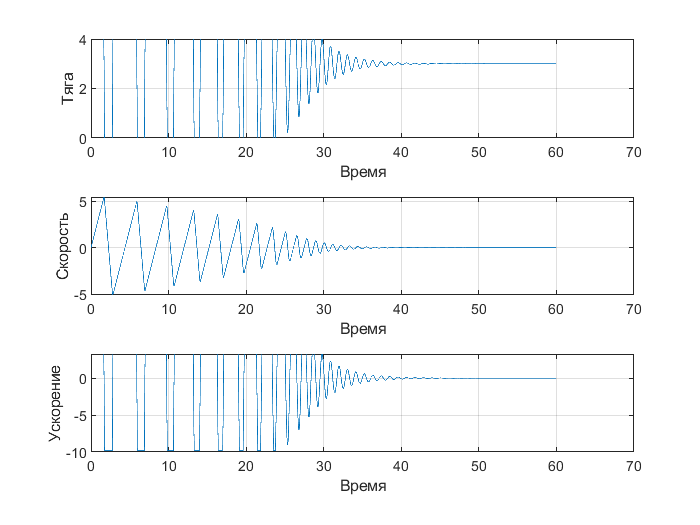


subplot(3,1,2)
plot(DATAT,DATAV)
grid on;
ylabel("Скорость")
xlabel("Время")

subplot(3,1,3)
plot(DATAT,DATAA)
grid on;
ylabel("Ускорение")
xlabel("Время")

subplot(3,1,1)
plot(DATAT,DATAF)
grid on;
ylabel("Тяга")
xlabel("Время")